## global body planner test

addpath(genpath('fpp_planner\'));
addpath(genpath('math\'));
x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = 200;
dt = 0.05;
[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

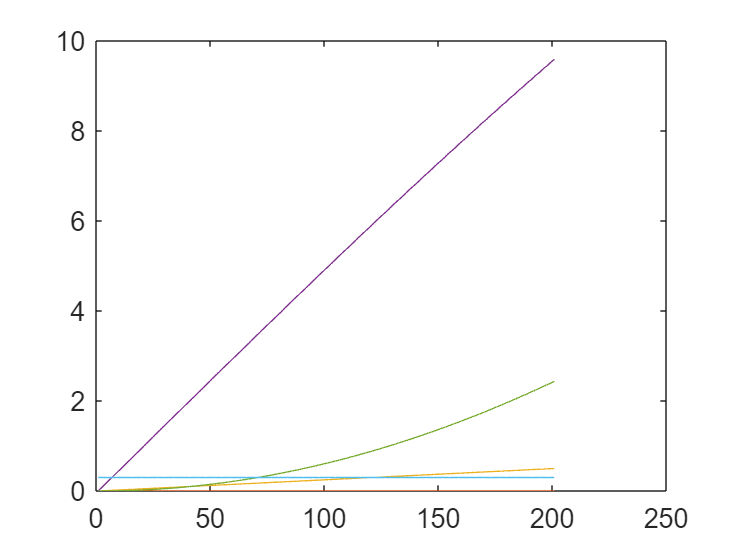


for i=1:6
plot(state_traj(i,:))
hold on
end

## local swing foot planner test

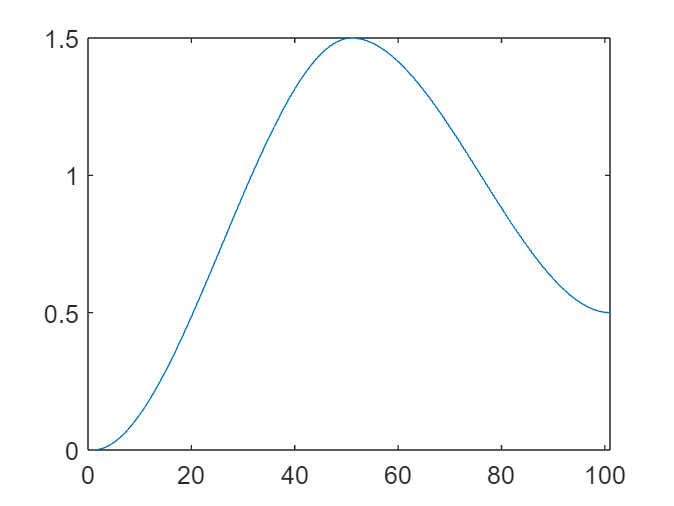

addpath(genpath('fpp_planner\'));
p_start = [-1;-1;0];
p_end = [1;1;0.5];
fp_h = 1.5;
fpp_arr = [];

for t_sw = 0:0.01:1
    fpp_t = swing_fpp_planner(p_start,p_end,fp_h,t_sw);
    fpp_arr = [fpp_arr, fpp_t];
end

clf;
plot(fpp_arr(3,:));

## stance fpp planner

addpath(genpath('fpp_planner\'));
addpath(genpath('math\'));

[world_p, body_p, ctr_p, path]...
    = hardware_params();

x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = ctr_p.mpc_horizon_steps;
dt_mpc = ctr_p.dt_mpc;

[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt_mpc)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


[ref_fpp_traj, ref_contact_event]...
    = stance_fpp_planner(state_traj, vel_tar, world_p, body_p, ctr_p)

ref_fpp_traj =     0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.4200    0.4272    0.4478    0.4803    0.5233    0.5751    0.6344    0.6997    0.7695    0.8422    0.9164    0.9906    1.0633    1.1331    1.1984    1.2577    1.3096    1.3525    1.3850    1.4056    1.4128    1.4128    1.4128    1.4128    1.4128    1.4128    1.4128    1.4128    1.4128    1.4128
    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1256    0.1260    0.1269    0.1283    0.1303    0.1326    0.1353    0.1382    0.1413    0.1446    0.1479    0.1513    0.1545    0.1576    0.1606    0.1632    0.1656    0.1675    0.1690    0.1699    0.1702    0.1702    0.1702    0.1702    0.1702    0.1702    0.1702    0.1702    

ref_contact_event =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     

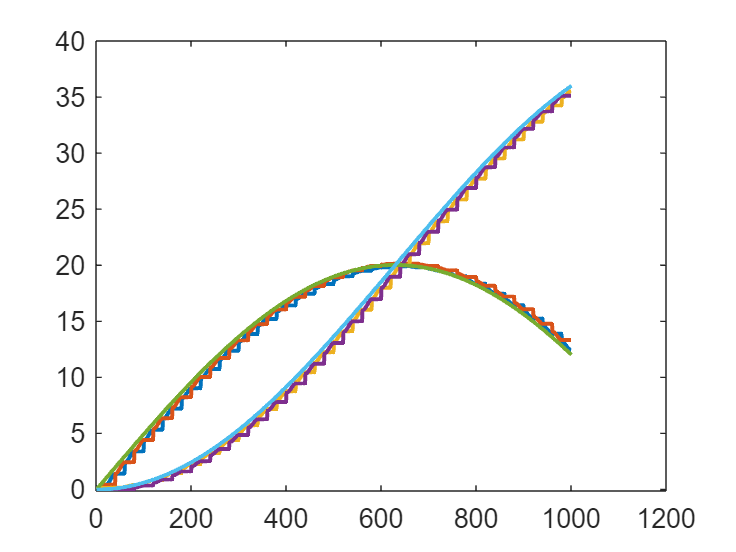

clf;
plot(ref_fpp_traj(1,:),'linewidth',1.5);
hold on
plot(ref_fpp_traj(4,:),'linewidth',1.5)
hold on
plot(ref_fpp_traj(2,:),'linewidth',1.5)
hold on
plot(ref_fpp_traj(5,:),'linewidth',1.5)
hold on

plot(state_traj(4,:),'linewidth',1.5)
hold on
plot(state_traj(5,:),'linewidth',1.5)
hold on